# 5.1. Волновое движение

#### Дифференциальное уравнение (волновое уравнение) распостранения

#### волны в одном измерении и его общее решение

clear
syms xi(x,t) c
diff(xi,x,2)==1/c^2*diff(xi,t,2)

$$ans(x, t) = \frac{\partial^{2}}{\partial x^{2}}\xi \left(x,t\right)=\frac{\frac{\partial^{2}}{\partial t^{2}}\xi \left(x,t\right)}{c^{2}}$$

syms f(x) g(x) x t
xi==f(x+c*t)+g(x-c*t)

$$ans(x, t) = \xi \left(x,t\right)=f\left(x+c\,t\right)+g\left(x-c\,t\right)$$

#### Решение для случая когерентных волн

syms xi xi0 k x x t delta
xi==xi0*sin(k*(x-c*t)-delta)

$$ans = \xi =-\xi_{0}\,\sin\left(\delta -k\,\left(x-c\,t\right)\right)$$

xi==xi0*exp(j*(k*(x-c*t)-delta))

$$ans = \xi =\xi_{0}\,{\mathrm{e}}^{-\delta \,\mathrm{i}+k\,\left(x-c\,t\right)\,\mathrm{i}}$$

####  Фундаментальные решения

syms lambda k T c nu omega sigma
lambda==2*pi/k==T*c

$$ans = \left(\lambda =\frac{2\,\pi }{k}\right)=T\,c$$

c==lambda*nu==omega/k

$$ans = \left(c=\lambda \,\nu \right)=\frac{\omega }{k}$$

T==1/nu==2*pi/(k*c)

$$ans = \left(T=\frac{1}{\nu }\right)=\frac{2\,\pi }{c\,k}$$

omega==2*pi*nu==k*c

$$ans = \left(\omega =2\,\pi \,\nu \right)=c\,k$$

sigma==1/lambda

$$ans = \sigma =\frac{1}{\lambda }$$

#### Фаза волны, если delta=0

syms phi
phi==k*(x-c*t)==k*x-omega*t==2*pi*(x/lambda-nu*t)==2*pi*(x/lambda-t/T)== ...
    2*pi*nu*(x/c-t)==2*pi*(sigma*x-nu*t)

$$ans = \left(\left(\left(\left(\left(\varphi =k\,\left(x-c\,t\right)\right)=k\,x-\omega \,t\right)=-2\,\pi \,\left(\nu \,t-\frac{x}{\lambda }\right)\right)=-2\,\pi \,\left(\frac{t}{T}-\frac{x}{\lambda }\right)\right)=-2\,\pi \,\nu \,\left(t-\frac{x}{c}\right)\right)=-2\,\pi \,\left(\nu \,t-\sigma \,x\right)$$

#### Продольная упругая волна (звуковая волна) в брусе

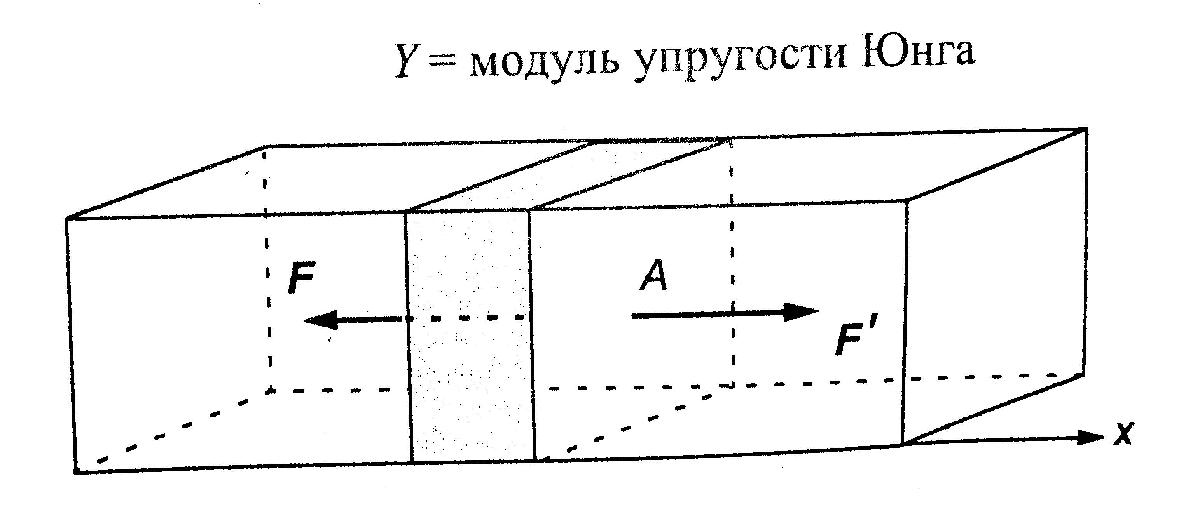

syms c_l Y rho F A xi(x)
c_l==sqrt(Y/rho)

$$ans = c_{l}=\sqrt{\frac{Y}{\rho }}$$

F/A==Y*diff(xi,x)

$$ans(x) = \frac{F}{A}=Y\,\frac{\partial }{\partial x}\xi \left(x\right)$$

#### Поперечная упругая волная в брусе

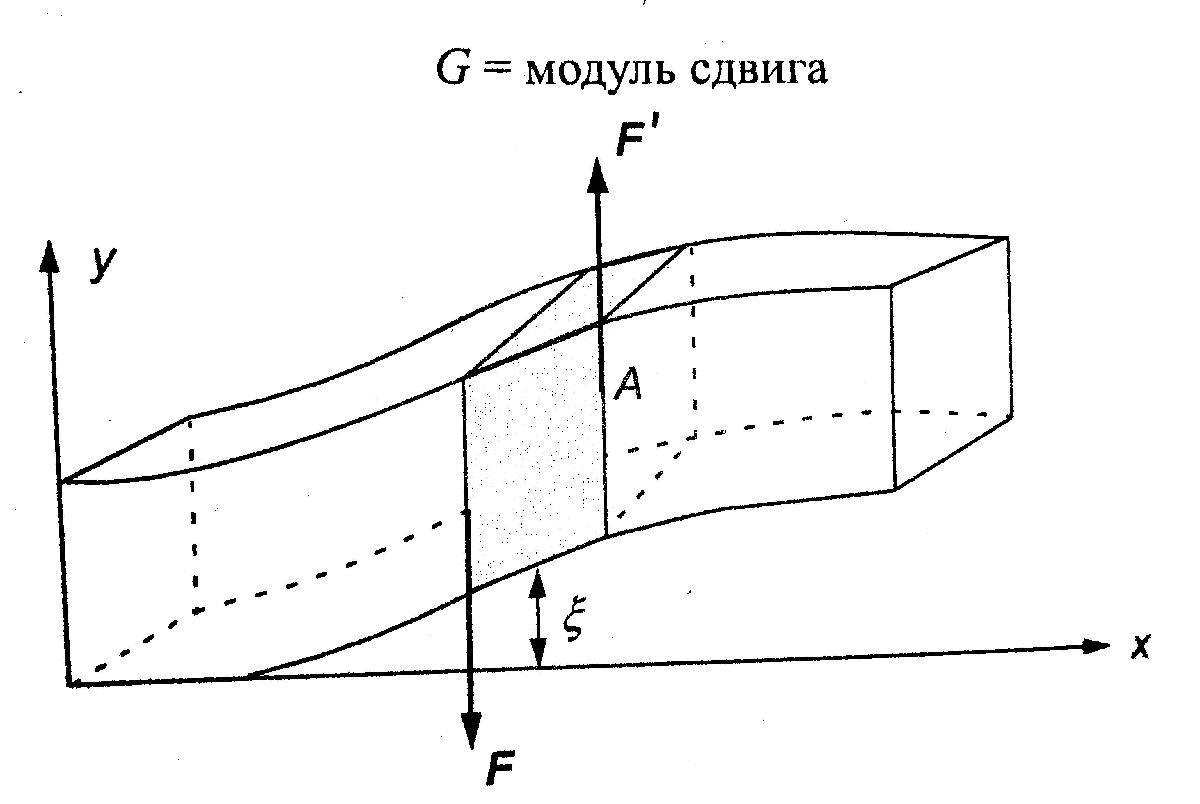

syms c_t G rho F A xi(x)
c_t==sqrt(G/rho)

$$ans = c_{t}=\sqrt{\frac{G}{\rho }}$$

F/A==G*diff(xi,x)

$$ans(x) = \frac{F}{A}=G\,\frac{\partial }{\partial x}\xi \left(x\right)$$

#### Продольная волна в пружине

syms c k l rho_l F Dl
c==sqrt(k*l/rho_l)

$$ans = c=\sqrt{\frac{k\,l}{\rho_{l}}}$$

F==k*Dl

$$ans = F=\mathrm{Dl}\,k$$

% rho = линейная плотность
% k = жесткость пружины
% l = длина пружины 

#### Поперечная волна в струне

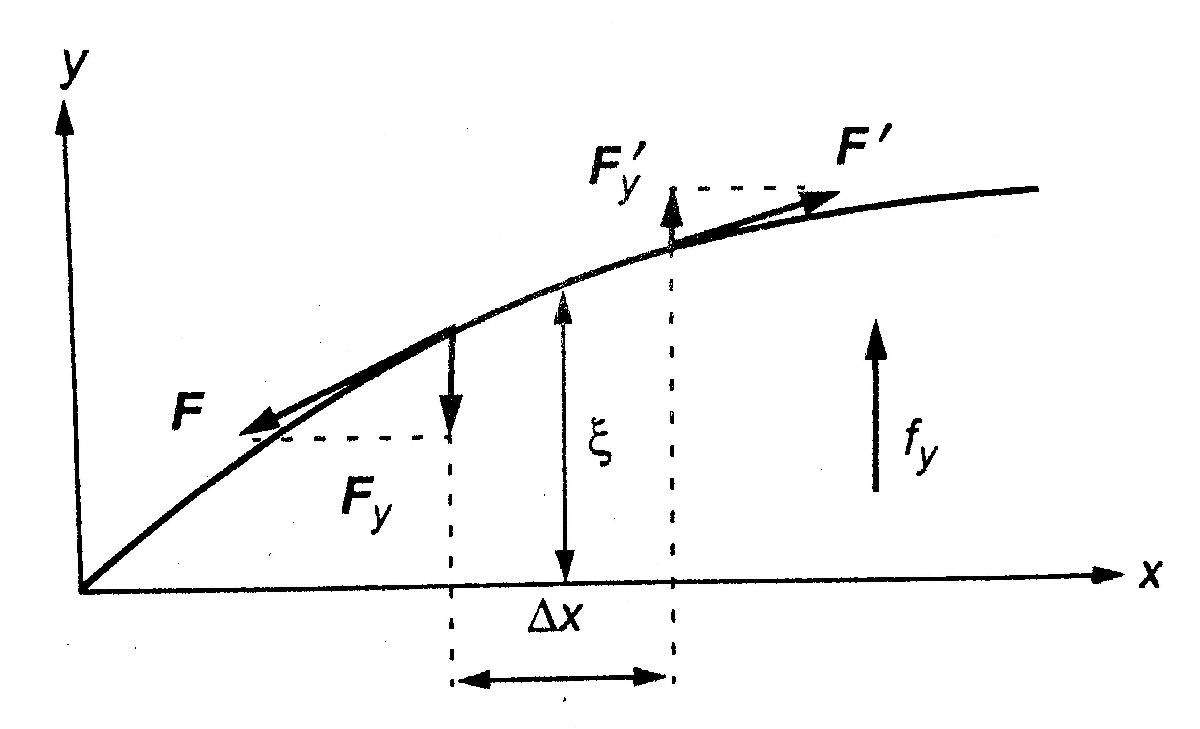

syms rho_l xi(x,t) F f_y
rho_l*diff(xi,t,2)==F*diff(xi,x,2)+f_y

$$ans(x, t) = \rho_{l}\,\frac{\partial^{2}}{\partial t^{2}}\xi \left(x,t\right)=F\,\frac{\partial^{2}}{\partial x^{2}}\xi \left(x,t\right)+f_{y}$$

В частности, в случае f_y=0, F=const

syms c F rho_l F_y F_y1 Dx
c==sqrt(F/rho_l)

$$ans = c=\sqrt{\frac{F}{\rho_{l}}}$$

(F_y-F_y1)/Dx==F*diff(xi,x,2)

$$ans(x, t) = \frac{F_{y}-F_{\mathrm{y1}}}{\mathrm{Dx}}=F\,\frac{\partial^{2}}{\partial x^{2}}\xi \left(x,t\right)$$

Граничное условие в случае незакрепленного конца 

diff(xi,x)==0

$$ans(x, t) = \frac{\partial }{\partial x}\xi \left(x,t\right)=0$$

#### Поперечные волны в мембране

syms c tau sigma0
c==sqrt(tau/sigma0)

$$ans = c=\sqrt{\frac{\tau }{\sigma_{0}}}$$

% tau = напряжение на единицу длины
% sigma0 = поверхностная плотность

#### Волна сжатия в газе (звуковая волна)

syms rho rho0 p p0 B xi(x)
rho-rho0==-rho0*diff(xi,x)

$$ans(x) = \rho -\rho_{0}=-\rho_{0}\,\frac{\partial }{\partial x}\xi \left(x\right)$$

p-p0==-B*diff(xi,x)

$$ans(x) = p-p_{0}=-B\,\frac{\partial }{\partial x}\xi \left(x\right)$$

% p = давление

Модуль объемного сжатия

syms B gamma p(rho) rho0 C_p C_V
B==gamma*p==-rho0*diff(p,rho) % |0

$$ans(rho) = \left(B=\gamma \,p\left(\rho \right)\right)=-\rho_{0}\,\frac{\partial }{\partial \rho }p\left(\rho \right)$$

gamma==C_p/C_V

$$ans = \gamma =\frac{C_{p}}{C_{V}}$$

Фазовая скорость 

syms c B rho0 gamma R T0 M mu alpha
c==sqrt(B/rho0)==sqrt(gamma*R*T0/M)==sqrt(gamma*k*T0/mu)==alpha*sqrt(T0)

$$ans = \left(\left(\left(c=\sqrt{\frac{B}{\rho_{0}}}\right)=\sqrt{\frac{R\,T_{0}\,\gamma }{M}}\right)=\sqrt{\frac{T_{0}\,\gamma \,k}{\mu }}\right)=\sqrt{T_{0}}\,\alpha$$

% T0 = температура
% k = постоянная Больцмана
% M = молекулярный вес
% R = универсальная газовая постоянная
% mu = масса молекулы
% alpha=20.055 м*с^(-1)*K^(-1/2) для воздуха

Амплитуда волны сжатия в случае гармонического осциллятора

syms P0 c omega rho0 xi0
P0==c*omega*rho0*xi0

$$ans = P_{0}=c\,\omega \,\rho_{0}\,\xi_{0}$$

#### Потенциал скоростей Phi для звуковой волны, если curl(v)=0 

syms v(x,y,z,t) grad(a) Delta(a) Phi(x,y,z,t) c rho rho0 
% Delta(a)=nabla2(a)
v==-grad(Phi)

$$ans(x, y, z, t) = v\left(x,y,z,t\right)=-\mathrm{grad}\left(\Phi \left(x,y,z,t\right)\right)$$

% v=v(x,y,z,t) = поле скоростей газа
Delta(Phi)==1/c^2*diff(Phi,t,2)

$$ans(x, y, z, t) = \Delta \left(\Phi \left(x,y,z,t\right)\right)=\frac{\frac{\partial^{2}}{\partial t^{2}}\Phi \left(x,y,z,t\right)}{c^{2}}$$

rho0*diff(Phi,t)==c^2*(rho-rho0)

$$ans(x, y, z, t) = \rho_{0}\,\frac{\partial }{\partial t}\Phi \left(x,y,z,t\right)=c^{2}\,\left(\rho -\rho_{0}\right)$$

#### Волна сжатия в жидкости

syms c B rho
c==sqrt(B/rho)

$$ans = c=\sqrt{\frac{B}{\rho }}$$

% B = модуль объемного сжатия

#### Электромагнитная волна 

syms c epsilon epsilon0 mu mu0
c==1/sqrt(epsilon*epsilon0*mu*mu0)

$$ans = c=\frac{1}{\sqrt{\epsilon \,\epsilon_{0}\,\mu \,\mu_{0}}}$$

#### Волны в воде

syms c g lambda S rho d
c==sqrt(g*lambda/(2*pi)+2*pi*S/(rho*lambda))   % для d>~lambda/4

$$ans = c=\sqrt{\frac{g\,\lambda }{2\,\pi }+\frac{2\,\pi \,S}{\lambda \,\rho }}$$

c==sqrt(g*d)         % для d<~lambda/12

$$ans = c=\sqrt{d\,g}$$

% S = коэффициент поверхностного натяжения (~0.074 Н/м)
% rho = плотность воды
% d = глубина воды
% Для цунами T ~ 1e3с и d<<lambda
% Для гравитационных волн 
omega^2==g*k*tanh(k*d)

$$ans = \omega^{2}=g\,k\,\tanh\left(d\,k\right)$$

#### Дифференциальное уравнение для распространения волны 

#### в трехмерном пространстве

syms xi Delta(x) c xi(r,t)
% Delta(x) = nabla2(x)
Delta(xi)==1/c^2*diff(xi(r,t),t,2)

$$ans = \Delta \left(\xi \left(r,t\right)\right)=\frac{\frac{\partial^{2}}{\partial t^{2}}\xi \left(r,t\right)}{c^{2}}$$

Решение для плоских гармонических волн

syms xi(r,t) xi0 k r sprod(x,y) omega t delta
xi==xi0*sin(sprod(k,r)-omega*t-delta)

$$ans(r, t) = \xi \left(r,t\right)=-\xi_{0}\,\sin\left(\delta +\omega \,t-\mathrm{sprod}\left(k,r\right)\right)$$

xi==xi0*exp(j*(sprod(k,r)-omega*t-delta))

$$ans(r, t) = \xi \left(r,t\right)=\xi_{0}\,{\mathrm{e}}^{-\delta \,\mathrm{i}-\omega \,t\,\mathrm{i}+\mathrm{sprod}\left(k,r\right)\,\mathrm{i}}$$

Решение в случае сферических гармонических волн 

syms xi(r,t) a r k omega t delta
xi==a/r*sin(sprod(k,r)-omega*t-delta)

$$ans(r, t) = \xi \left(r,t\right)=-\frac{a\,\sin\left(\delta +\omega \,t-\mathrm{sprod}\left(k,r\right)\right)}{r}$$

% a = константа